# Inputs

T = 1200; % Sample time
Ts = 10; % Points number
T_simple = 120;

Ptake_off = 1300;
Pmax = 1500;
Pmid = 1250;
Pcruise = 850;
Pdesc = 700;

# Flight scheme with noise

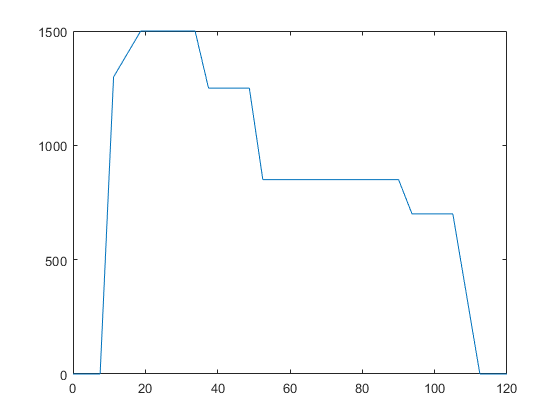

T1 = 2/100*T;
T2 = 1/100*T;
T3 = 2/100*T;
T4 = 4/100*T;
T6 = 1/100*T;
T7 = 3/100*T;
T8 = 1/100*T;
T9 = 10/100*T;
T10 = 1/100*T;
T11 = 3/100*T;
T12 = 2/100*T;
T13 = 2/100*T;


% start + take off
F1 = linspace(0,0,T1*Ts);
F2 = linspace(0,Ptake_off,T2*Ts);
a = [F1 F2];
u = "takeoff";
al = repelem(u,length(a));

% climb + max power
F1 = linspace(Ptake_off,Pmax,T3*Ts);
F2 = linspace(Pmax,Pmax,T4*Ts);
F3 = linspace(Pmax,Pmid,T6*Ts);
b = [F1 F2 F3];
u = "climb";
bl = repelem(u,length(b));

% mid to cruise
F3 = linspace(Pmid,Pmid,T7*Ts);
F4 = linspace(Pmid,Pcruise,T8*Ts);
F5 = linspace(Pcruise,Pcruise,T9*Ts);
c = [F3 F4 F5];
u = "cruise";
cl = repelem(u,length(c));

% descend + landing
F1 = linspace(Pcruise,Pdesc,T10*Ts);
F2 = linspace(Pdesc,Pdesc,T11*Ts);
F3 = linspace(Pdesc,0,T12*Ts);
F4 = linspace(0,0,T13*Ts);
d = [F1 F2 F3 F4];
u = "descend";
dl = repelem(u,length(d));

clf;
one_c = [a b c d];
leg = [al bl cl dl];

t_one_c = linspace(0,T_simple,length(one_c));
to_classify_1 = [t_one_c' one_c' leg'];
to_classify_1 = array2table(to_classify_1,...
    'VariableNames',{'time','power','legend'});
load_oc_without_noise = [t_one_c; one_c];
plot(t_one_c,one_c);

% plot(load_oc_without_noise);
% save('load_oc_without_noise.mat',"load_oc_without_noise")

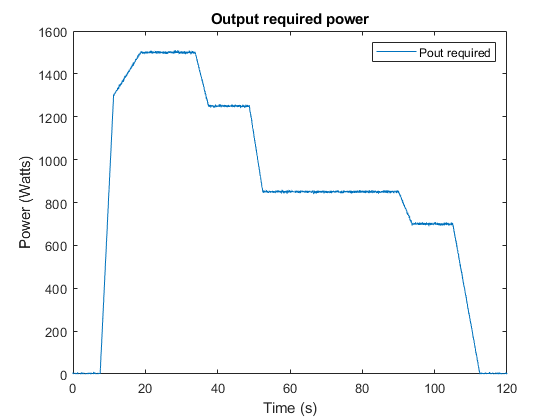

% With noise
t_one_c_bis = t_one_c;
one_c_bis = awgn(one_c,50,'measured');
plot(t_one_c,one_c_bis);
legend('Pout required');
title('Output required power');
ylabel('Power (Watts)');
xlabel('Time (s)');
ylim([0 1600]);

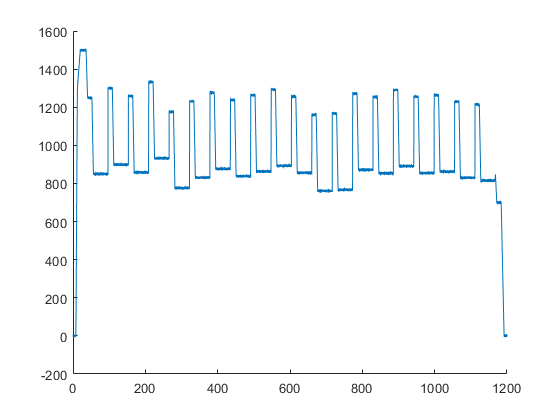



cycle = 20;
temp = [a b c];
templ = [al bl cl];
for i=1:cycle-1
    temp = [temp c+ randi([-100 100])];
    templ = [templ cl];
end
temp = [temp d];
templ = [templ dl];
c_repeated = awgn(temp,50,'measured');



t_repeated = linspace(0,T,length(c_repeated));

clf;
% plot(t,x)
hold on;
plot(t_repeated,c_repeated)


to_classify_2 = [t_repeated' c_repeated' templ'];
to_classify_2 = array2table(to_classify_2,...
    'VariableNames',{'time','power','legend'});
save('test_load.mat','t_one_c','one_c','t_one_c_bis','one_c_bis','t_repeated','c_repeated','leg','templ','to_classify_1','to_classify_2')
% save(strcat(fileparts(pwd),'\data.mat'),'one_c','t_one_c','w','t')

# Load to train

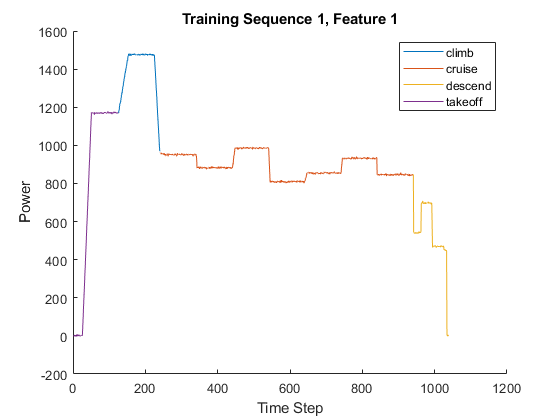

load("test_load.mat")
XTrain = {};
YTrain = {};
YTrainNN = {};
hold off;

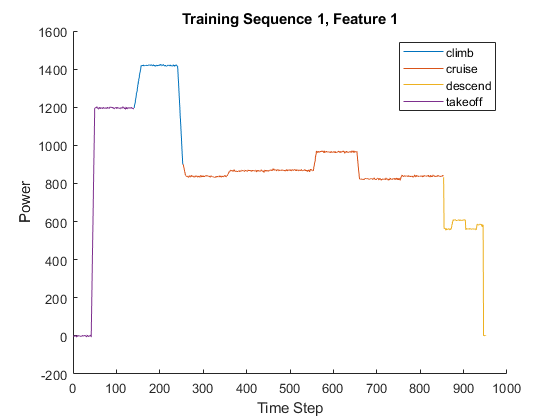

nbpoints = 100;
tot_profile = [];
tot_leg = [];
tot_time = [];
tot_leg_number = [];

%% Basic
for j=1:50
    profile = [0];
    leg = ["takeoff"];
    t = [0];
    leg_number = [0];


    takeOffTime = 30+randi(30);
    [temppower, templeg,tempt] = take_off(takeOffTime, nbpoints, 1250,t(end));
    profile = [profile temppower];
    leg = [leg templeg];
    t = [t tempt];
    leg_number = [leg_number zeros(1,length(templeg))];

    climbingTime = 70+randi(30);
    [temppower, templeg,tempt] = climb(climbingTime, nbpoints, profile(end), 1500,t(end));
    profile = [profile temppower];
    leg = [leg templeg];
    t = [t tempt];
    leg_number = [leg_number zeros(1,length(templeg))+1];
    
    mxp = 800 + randi(200);
    % little desc
    desc = 0.1+randi(10)/100;
    F1 = linspace(profile(end),mxp,desc*nbpoints);
    profile_ = [F1];
    leg_ = repelem("climb",length(profile_));
    t_ = linspace(t(end),t(end)+desc*climbingTime,length(profile_));
    profile = [profile profile_];
    leg = [leg leg_];
    t = [t t_];
    leg_number = [leg_number zeros(1,length(leg_))+1];
    
    maax = 5+randi(2);
    for i = 1:maax
        [temppower, templeg,tempt] = cruise(40+randi(50), nbpoints, profile(end), 800,t(end));
        profile = [profile temppower];
        leg = [leg templeg];
        t = [t tempt];
        leg_number = [leg_number zeros(1,length(templeg))+2];
    end

    [temppower, templeg,tempt] = descend(takeOffTime+climbingTime, nbpoints, profile(end),t(end));
    profile = [profile temppower];
    leg = [leg templeg];
    t = [t tempt];
    leg_number = [leg_number zeros(1,length(templeg))+3];

    XTrain{j} = awgn(profile,50,'measured');
    YTrain{j} = categorical(leg);
    YTrainNN{j} = leg_number;
    
    tot_profile = [tot_profile profile];
    tot_leg = [tot_leg leg];
    tot_time = [tot_time t];
    tot_leg_number = [tot_leg_number leg_number];
end


%% Multiple landing / take off
% for j=1:10
%     profile = [0];
%     leg = ["takeoff"];
%     t = [0];
%     
%     
%     catg = ["takeoff", "climb", "cruise", "descend"];
%     old_catg = "";
%     c = 0;
%     
%     maax = 10+randi(10);
%     for i = 1:maax
%         randomIndex = randi(length(catg), 1);
%         catg_value = catg(randomIndex);
%         if ((strcmp(catg_value,"takeoff") && strcmp(old_catg,"descend")) || length(t) == 1) && (c==1 || c==0)
%             takeOffTime = 30+randi(30);
%             [temppower, templeg,tempt] = take_off(takeOffTime, nbpoints, 1000,t(end));
%             profile = [profile temppower];
%             leg = [leg templeg];
%             t = [t tempt];
%             climbingTime = 70+randi(30);
%             [temppower, templeg,tempt] = climb(climbingTime, nbpoints, profile(end), 1500,t(end));
%             profile = [profile temppower];
%             leg = [leg templeg];
%             t = [t tempt];
%             c = c+2;
%             old_catg = catg_value;
%         end
%         
%         
%         if strcmp(catg_value,"climb") && ~strcmp(old_catg,"descend") && c > 3
%             climbingTime = 70+randi(30);
%             [temppower, templeg,tempt] = climb(climbingTime, nbpoints, profile(end), 1500,t(end));
%             profile = [profile temppower];
%             leg = [leg templeg];
%             t = [t tempt];
%             c = c+1;
%             old_catg = catg_value;
%         end
%         
%         if strcmp(catg_value,"cruise") && ~strcmp(old_catg,"descend")
%             [temppower, templeg,tempt] = cruise(10+randi(50), nbpoints, profile(end), 800,t(end));
%             profile = [profile temppower];
%             leg = [leg templeg];
%             t = [t tempt];
%             c = c+1;
%             old_catg = catg_value;
%         end
%         
%         if strcmp(catg_value,"descend") && ~strcmp(old_catg,"descend")  && c > 5
%             if strcmp(old_catg,"climb")
%                 [temppower, templeg,tempt] = cruise(10+randi(50), nbpoints, profile(end), 800,t(end));
%                 profile = [profile temppower];
%                 leg = [leg templeg];
%                 t = [t tempt];
%             end
%             [temppower, templeg,tempt] = descend(takeOffTime+climbingTime, nbpoints, profile(end),t(end));
%             profile = [profile temppower];
%             leg = [leg templeg];
%             t = [t tempt];
%             c = 1;
%             old_catg = catg_value;
%         end
%         
%     end
%     if ~strcmp(old_catg,"descend")
%         if strcmp(old_catg,"climb")
%             [temppower, templeg,tempt] = cruise(10+randi(50), nbpoints, profile(end), 800,t(end));
%             profile = [profile temppower];
%             leg = [leg templeg];
%             t = [t tempt];
%         end
%         [temppower, templeg,tempt] = descend(takeOffTime+climbingTime, nbpoints, profile(end),t(end));
%         profile = [profile temppower];
%         leg = [leg templeg];
%         t = [t tempt];
%         c = 1;
%     end
%     
%     
%     XTrain{j} = profile;
%     YTrain{j} = categorical(leg);
% end

to_classify = [tot_time' tot_profile' tot_leg' tot_leg_number'];
to_classify = array2table(to_classify,...
    'VariableNames',{'time','power','legend','legend_number'});

save('load_to_train',"XTrain","YTrain","YTrainNN","to_classify")

X = XTrain{1}(1,:);
classes = categories(YTrain{1});

figure
for j = 1:numel(classes)
    label = classes(j);
    idx = find(YTrain{1} == label);
    hold on
    plot(idx,X(idx))
end
hold off

xlabel("Time Step")
ylabel("Power")
title("Training Sequence 1, Feature 1")
legend(classes,'Location','northeast')

# Set a basic Test

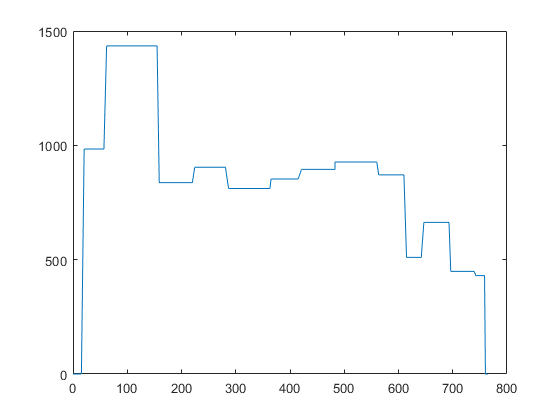

XTest = {};
YTest = {};
profile = [0];
leg = ["takeoff"];
t = [0];
leg_number = [0];


takeOffTime = 30+randi(30);
[temppower, templeg,tempt] = take_off(takeOffTime, nbpoints, 1000,t(end));
profile = [profile temppower];
leg = [leg templeg];
t = [t tempt];
leg_number = [leg_number zeros(1,length(templeg))];

climbingTime = 70+randi(30);
[temppower, templeg,tempt] = climb(climbingTime, nbpoints, profile(end), 1500,t(end));
profile = [profile temppower];
leg = [leg templeg];
t = [t tempt];
leg_number = [leg_number zeros(1,length(templeg))+1];

maax = 5+randi(5);
for i = 1:maax
    [temppower, templeg,tempt] = cruise(40+randi(50), nbpoints, profile(end), 800,t(end));
    profile = [profile temppower];
    leg = [leg templeg];
    t = [t tempt];
    leg_number = [leg_number zeros(1,length(templeg))+2];
end

[temppower, templeg,tempt] = descend(takeOffTime+climbingTime, nbpoints, profile(end),t(end));
profile = [profile temppower];
leg = [leg templeg];
t = [t tempt];
leg_number = [leg_number zeros(1,length(templeg))+3];

plot(t,profile)

XTest{1} = profile;
YTest{1} = categorical(leg);
to_try = [t' profile' leg' leg_number'];
to_try = array2table(to_try,...
    'VariableNames',{'time','power','legend','legend_number'});
save('load_to_test',"XTest","YTest","to_try")
